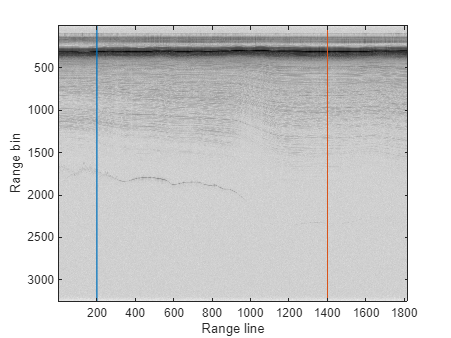

clear all
close all
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20240105_02\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20240105_02\

load Data_img_01_20240105_02_005.mat
load Data_20240105_02_005.mat

% load echogram!
echo = load('Data_img_01_20240105_02_005.mat','Data','Time','GPS_time');
h_fig = figure;
h_axes = axes;
imagesc(lp(echo.Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);
hold on
y = linspace(0, size(Data, 1), size(Data, 1));
x1 = linspace(200, 200, size(Data, 1));
x2 = linspace(1400, 1400, size(Data, 1));
plot(x1, y)
plot(x2, y)

hold off
brightness1 = Data(:, 200)';
brightness2 = Data(:, 1400)';

tiledlayout(2, 1)

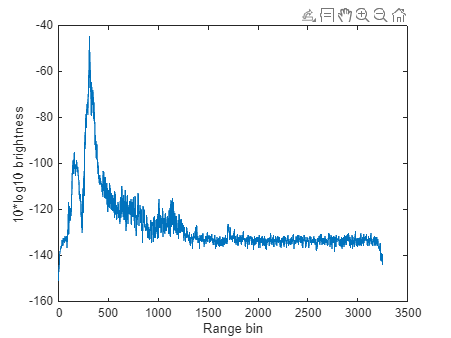

plot(y, 10*log10(brightness1))
xlabel('Range bin');
ylabel('10*log10 brightness ');
nexttile

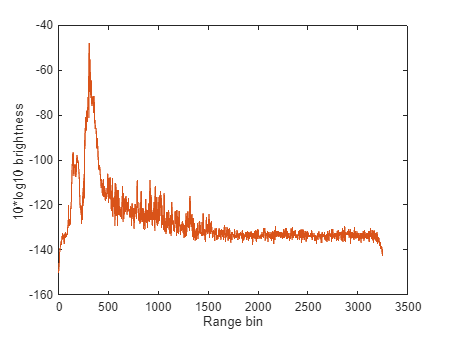


plot(y, 10*log10(brightness2), 'Color', "#D95319")
xlabel('Range bin');
ylabel('10*log10 brightness ');


% plot(y, 10*log10(brightness2))

power = calibrateBrightness(20240105, 02, 005);

outputBrightness = 1.0e-10 *

    0.0003    0.0003    0.0003    0.0002    0.0002    0.0003    0.0003    0.0004    0.0008    0.0005    0.0007    0.0006    0.0003    0.0002    0.0002    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0003    0.0001    0.0000    0.0000    0.0001


depth = twtt2Depth(twtt, 1.77); % row 1 = surface, row 2 = bottom :) 

depth = 1.0e+03 *

    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3424    0.3429    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430
    2.6344    2.6347    2.6333    2.6301    2.6275    2.6270    2.6274    2.6282    2.6286    2.6287    2.6293    2.6303    2.6319    2.6336    2.6347    2.6353    2.6355    2.6347    2.6330    2.6301    2.6265    2.6247    2.6237    2.6221    2.6200    2.6174    2.6147    2.6119    2.6095    2.6076    2.6063    2.6053    2.6056    2.6067    2.6098    2.6138    2.6191    2.6226    2.6225    2.6216    2.6207    2.6197    2.6188    2.6159    2.6124    2.6102    2.6087    2.6084


test = 10*log10(Surface)

test =   -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9331  -53.9254  -53.9254  -53.9254  -53.9254  -53.9254  -53.9254  -53.9254  -53.9254  -53.9254  -53.9254  -53.9254  -53.9254  -53.9254  -53.9268  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362  -53.9362
